# Forced NLS Demo

The nonlinear Schrodinger equation on a dumbbell graph, subject to a nonhomogeneous Robin-Kirchhoff vertex condition at vertex 1.

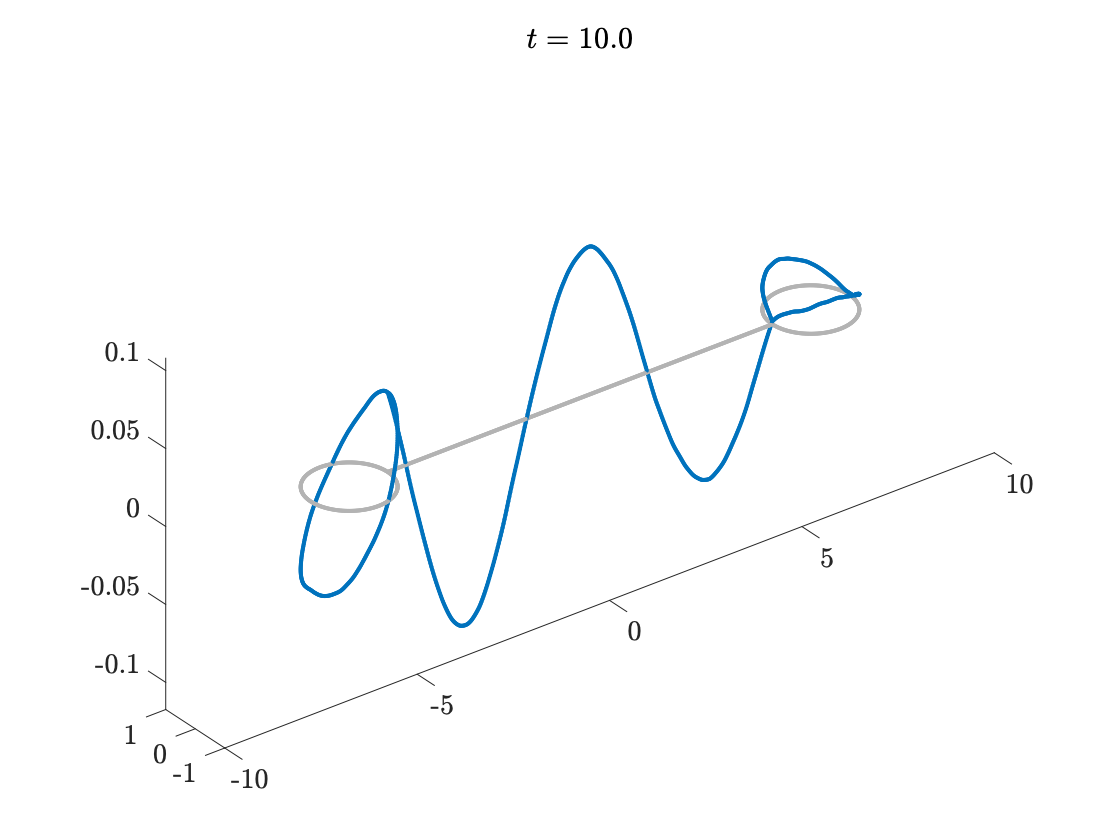

LVec=[2*pi 10 2*pi];
nX=40;
Phi=quantumGraphFromTemplate('dumbbell','LVec',LVec,'nX',nX);
u0=Phi.applyFunctionsToAllEdges({0,0,0});

phiNode=@(t)[0.1*exp(1i*t);0];
mu = -1i;
F=@(t,z) -2i * z.^2 .* conj(z);
tFinal = 10;
t=0:.25:tFinal;

[t,u] = Phi.odeQG23t(mu,F,t,u0,'phi',phiNode,'tol',1e-6);

animatePDESolution(Phi,real(u),t);